folder = "DB2"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  %subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  %imshow(Im{i}) %%Show the current image in a subplot.
end

Convert to YCbCr and create an eye map according to the *Face Detection in Color Images* paper.

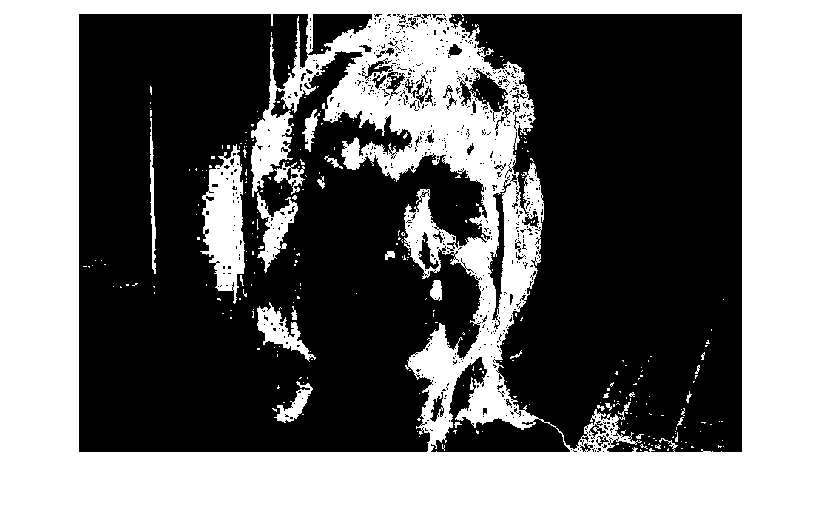

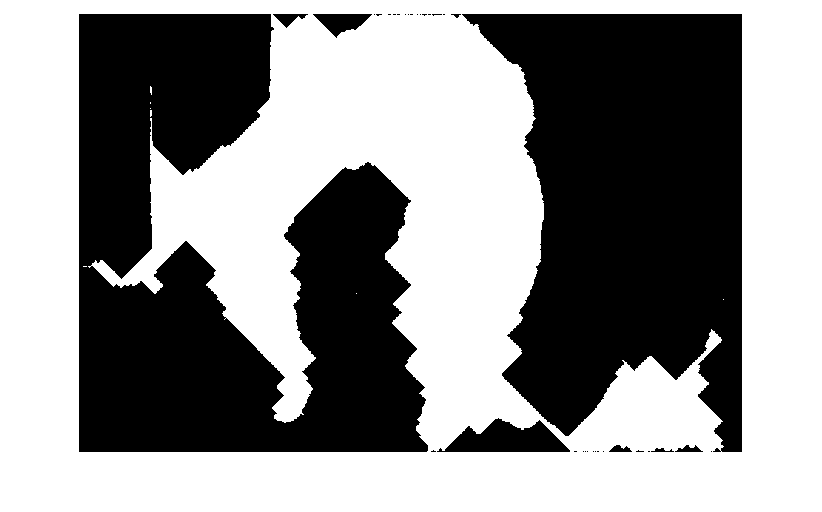

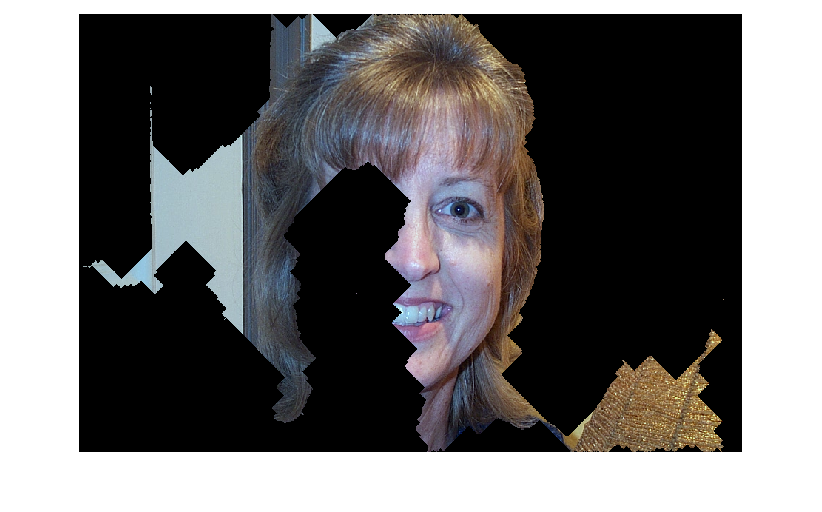

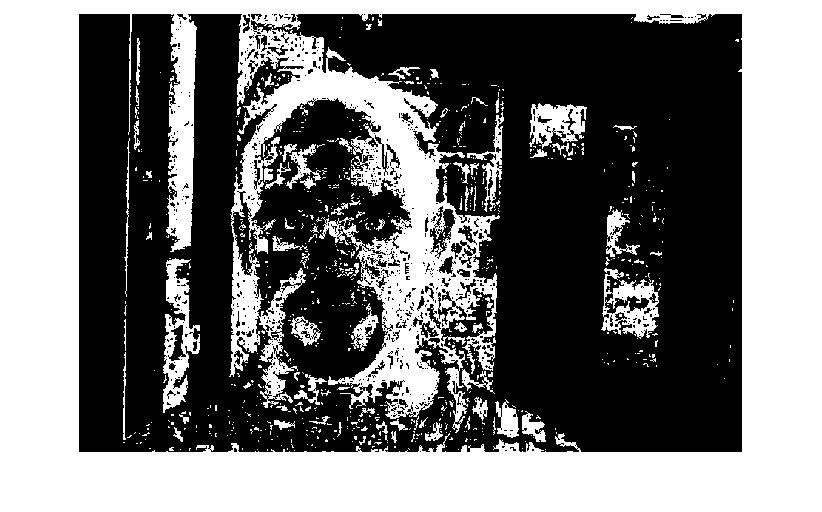

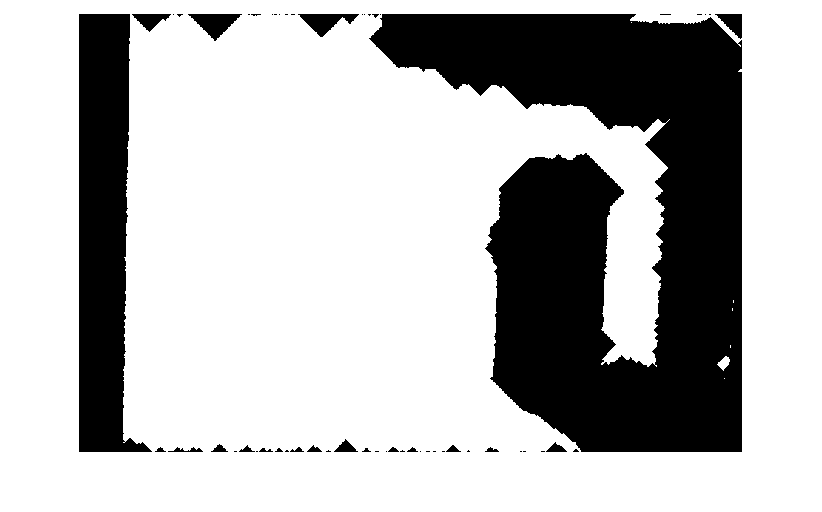

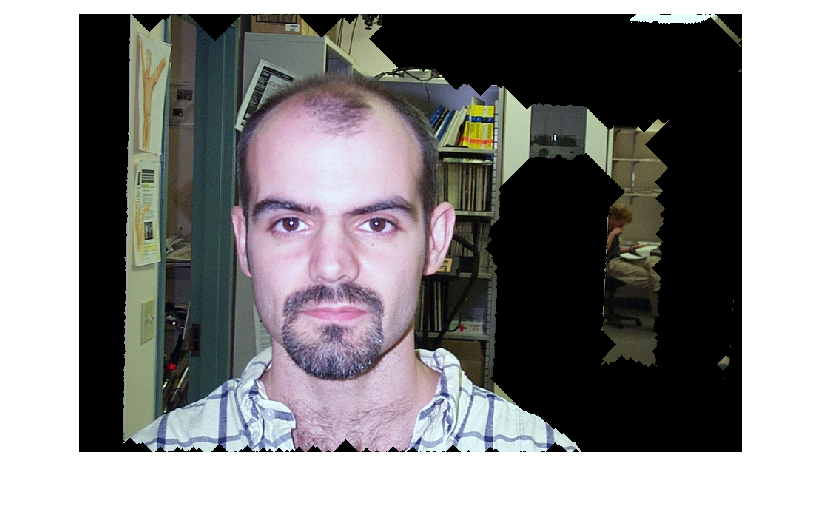

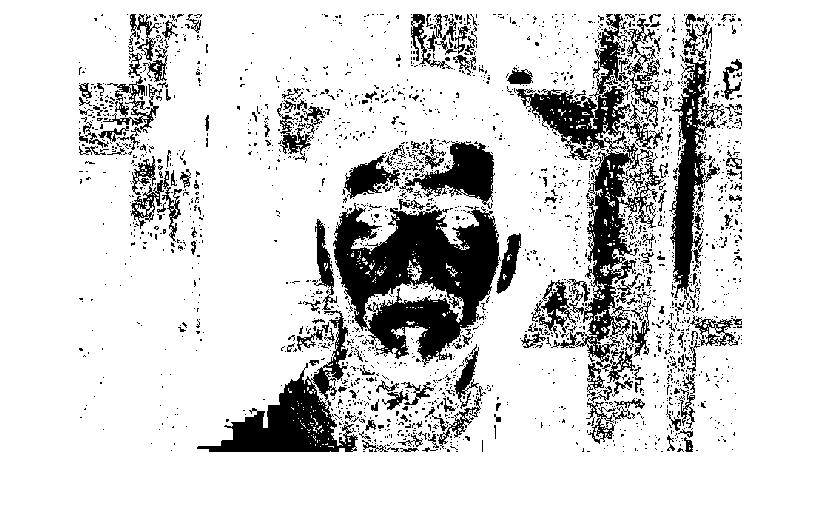

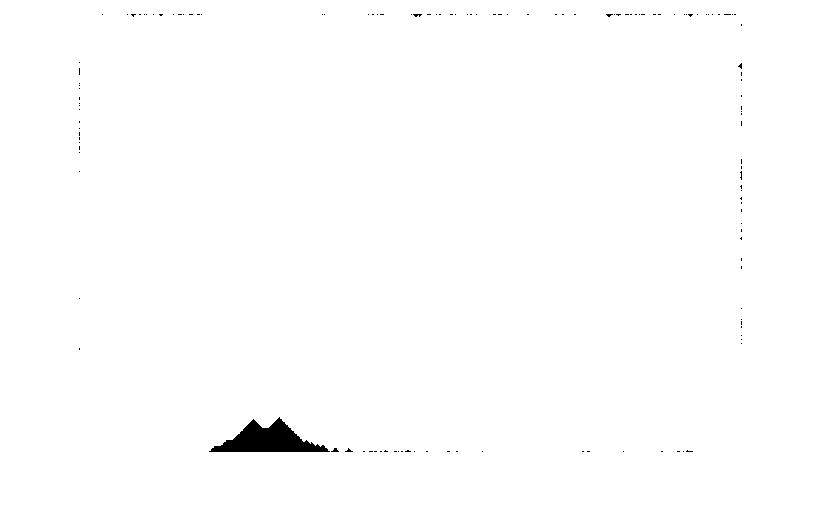

%The following requires image processing toolbox.

for i = 34:length(Im)


%subplot(6,7, i); %%define location to plot the image in our subplot.
    currentImage = Im{i};

skin = skinmask(currentImage, 0.0001);
currentImage = lighting_compensation(currentImage,0.20);
masked_image = currentImage .* skin;



% EyeMap = eye_detection(masked_image);
% 
% size_img = size(currentImage);
% 
% MouthMap = mouth_detection(masked_image);
% 
% [lEye_c, rEye_c, mouth_c, e_regions,m_regions ] = face_triangle_coordinates(MouthMap, EyeMap);



figure
imshow(masked_image)
%imshow(EyeMap)
hold on
% plot([1,size_img(2)],[3/5*size_img(1),3/5*size_img(1)],'Color','b','LineWidth',2)
% plot([1,size_img(2)],[2/5*size_img(1),2/5*size_img(1)],'Color','b','LineWidth',2)
% plot([1,size_img(2)],[3.9/5*size_img(1),3.9/5*size_img(1)],'Color','b','LineWidth',2)
%plot([lEye_c(1),rEye_c(1)],[lEye_c(2),rEye_c(2)],'Color','r','LineWidth',2)
%plot([mouth_c(1),rEye_c(1)],[mouth_c(2),rEye_c(2)],'Color','r','LineWidth',2)
%plot([mouth_c(1),lEye_c(1)],[mouth_c(2),lEye_c(2)],'Color','r','LineWidth',2)
 %for idx = 1:length(m_regions)
%     plot(m_regions(idx).Centroid(1),m_regions(idx).Centroid(2), 'x', 'markersize', 8, "LineWidth",2, 'Color', 'green')
% 
% end
% for idx = 1:length(e_regions)
%     plot(e_regions(idx).Centroid(1),e_regions(idx).Centroid(2), 'o', 'markersize', 8, "LineWidth",2, 'Color', 'yellow')
% 
% end

hold off

end 